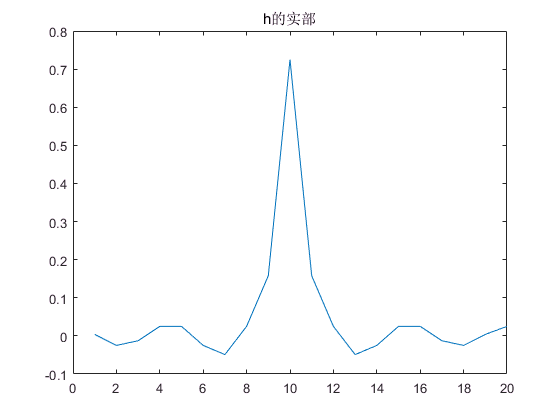

H_amp = [1, 1, 1, 1, 1, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 1, 1, 1, 1];

N = length(H_amp);

w0 = 2 * pi / length(H_amp);

theta = (w0 * fix(N/2)) .* [0 : 1 : N-1];

H_phase = exp(-1i .* theta);

H = H_amp .* H_phase;

h = ifft(H);

%h = circshift(h',fix(N/2))';


plot(real(h));
title("h的实部");

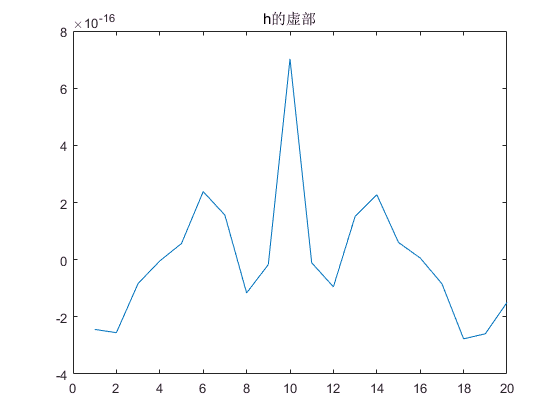


plot(imag(h));
title("h的虚部");

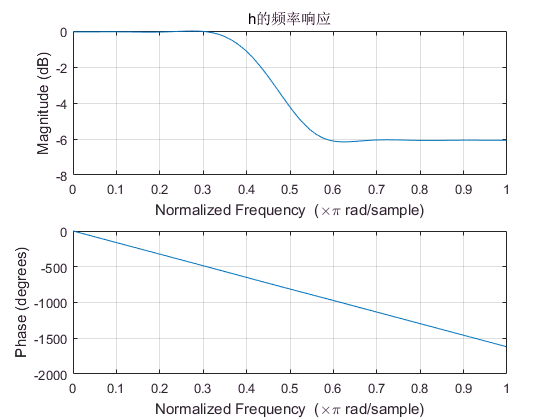


window = hanning(N);

h = h .* window';

freqz(real(h));
title("h的频率响应");